clear
n = 10;
mu = 0.01

mu = 0.0100

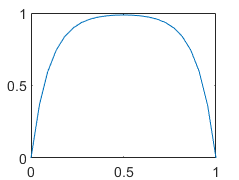

addpath('../');
[u, fu, dfu] = fem_p2(n, mu);
plot(linspace(0, 1, size(u,1)), u)

uu = [0]

uu = 0

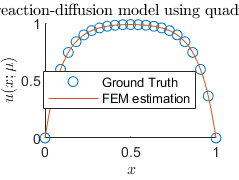

xx = linspace(0, 1, 2*n + 3);
h = 1/(n+1);

for j = 1:2:2*n+1
    a = xx(j);
    b = xx(j+2);
    f = fu{(j+1)/2};
    xcurr = linspace(a, b, 10)';
    ucurr = f(xcurr);
    uu = [uu; ucurr(2:end)];
end

scatter(xx, u_true(xx, mu))
hold on
plot(linspace(0, 1, size(uu, 1)), uu)
xlabel('\(x\)', 'Interpreter','latex')
ylabel('\(u(x; \mu)\)', 'Interpreter','latex')
title(sprintf("Finite Element method on reaction-diffusion model using quadratic coefficients, \\(\\mu = %f \\) ", mu), "Interpreter","latex")
legend("Ground Truth", "FEM estimation", 'Location', '')
saveas(gcf, "fem_p2.png")
saveas(gcf, "fem_p2.pdf")